## Formler

1.1, 1.3, 1.7, 1,12b) og c), 1.12e

### Fourier’s law.

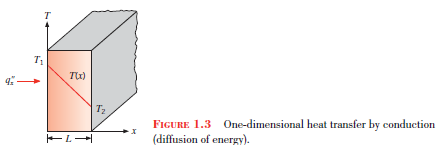

### Newton’s law of cooling

convective heat flux

net rate of radiation heat transfer from the surface

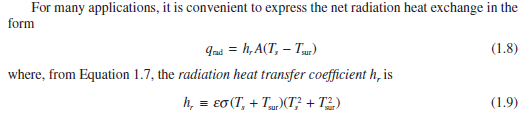

### conservation statement

simplified steady-flow thermal energy equation:

**Opgaver**

**Opgave 1.30**

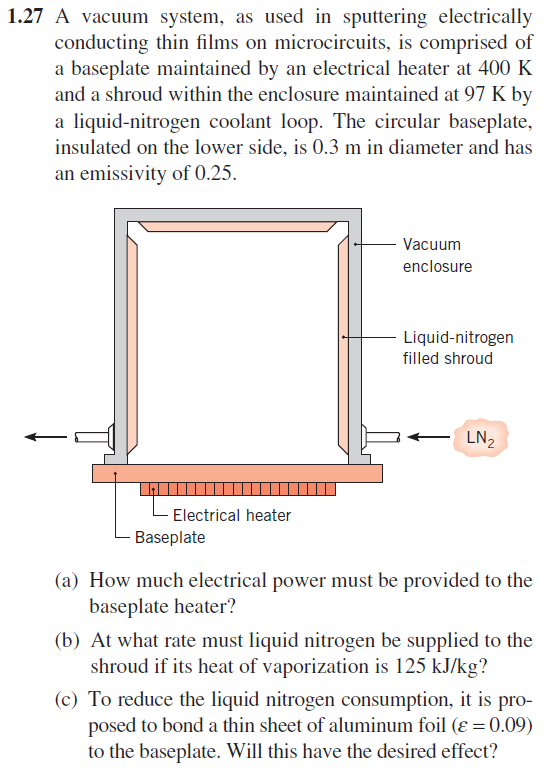

Først opstilles et "energi" diagram / tegning og der opstilles antagelser.

- Der er intet tab i electronikken, alt strøm går til stråling.

- Ingen ydre faktorer har en betydning kun strålingen og nitrogenen

- Systemet er i lige vægt og stabilt

- Alt stråling optages af nitrogenen

- Strålingen er ideel med emissivity - "grey surface" $\alpha = \epsilon$

- For emissivity er overfladen meget vigtig

Vi opstiller et energi regnskab fra de energi ændringer der er i systmet i lige vægt


$$E_{str\aa ling}  = E_{nitrogen}$$


**a)**

T_heater = 400; %K
T_shroud = 97; %K
d=0.3; %m
epsilon = 0.25; %emesivitet
sigma = 5.67 * 10^-8; % J/K %stefan-boltzman konstant
A = pi*(d/2)^2;
q = A*epsilon * sigma * (T_heater^4 - T_shroud^4) % W

q = 25.5618

Alt strøm går til stråling

**b)**

**Vi finder masse strømmen af nitrogen**


$$q_{str\aa ling} =  q_{nitrogen} = \dot{m} \cdot L_f$$


l_f = 125000 %kJ/kg %opslag

l_f = 125000

%Q = m*L_f
m_dot = q/l_f %masse strømmen kg/s

m_dot = 2.0449e-04

m_dot_hours = m_dot * 60 * 60 %masse strømmen kg/hr

m_dot_hours = 0.7362

supplie 0,205 gram per s or 0,7362 kg per time

**c)**

Ja - vi laver smame udregning med ny epsilonværdi


$$\epsilon_{alu}\cdot \sigma A \left(T_s^4 - T_{sur}^4\right) = \dot{m} \cdot L_f$$


epsilon_alu = 0.09

epsilon_alu = 0.0900

q_alu = q * (epsilon_alu/epsilon) % vi tager og divdere q med epsilon og ganger med epsilon alu istedet.

q_alu = 9.2022


m_dot = q_alu/l_f %masse stræmmen kg/s

m_dot = 7.3618e-05


m_dot_hours = m_dot * 60 * 60

m_dot_hours = 0.2650

Kun emissivtiviteten benyttes

**Opgave 1.48**

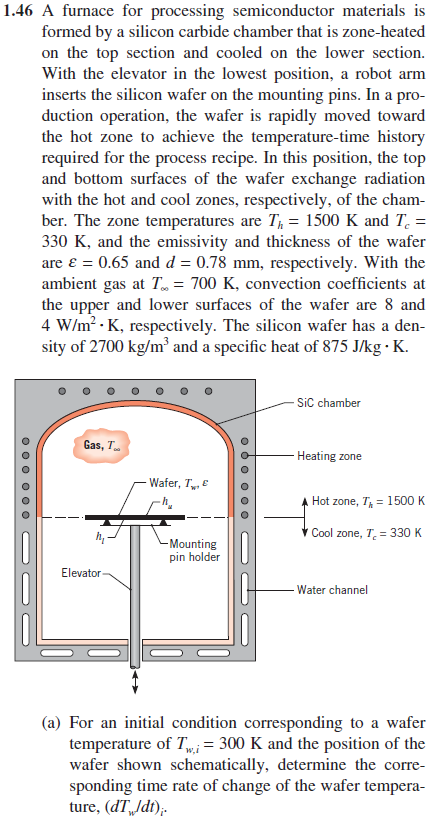

ASSUMPTIONS: 

(1) Wafer temperature is uniform, 

(2) Transient conditions when wafer is initially positioned, 

(3) Hot and cool zones have uniform temperatures, 

(4) Radiation exchange is between small surface (wafer) and large enclosure (chamber, hot or cold zone),

(5) Negligible heat losses from wafer to mounting pin holder.

**a)**

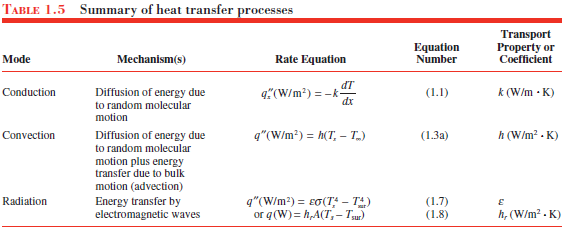

**forstå hver led bedre**

her er $\dot{q} \left[W/m^3  = \frac{m^2 \cdot kg}{m^3 \cdot s^{3}}\right]$er rate of generation per unit volume

og $q'' [W/m^2]$ er varmefluxen

kun i y retningen 

der gange med d på begge side og isoleres nu for $\frac{\partial T}{\partial t}$

clear all
T_h = 1500; %K 
T_c = 330; %K
epsilon = 0.65; % emmisiviteten fra wafer
d = 0.78 *1e-3; %thickness of wafer %m
T_amb = 700 %K gas temperaturen

T_amb = 700

sigma = 5.67 * 10^-8; % J/K
h_up = 8 % W/m^2*K %convections coefficenten top

h_up = 8

h_low = 4 % W/m^2*K  %convections coefficenten bund

h_low = 4


rho_SiC = 2700; % kg/m^3 %wafer density
c_p =  875; % J/kg*K wafer specific heat
T_wi = 300; %K % intial wafer temperatur

q_con_h = h_up * (T_wi - T_amb) %convection above plate

q_con_h = -3200

q_con_l = h_low * (T_wi- T_amb) %convection below plate

q_con_l = -1600

q_rad_h = epsilon * sigma * (T_h^4 - T_wi^4) %radiation above plate

q_rad_h = 1.8628e+05

q_rad_l = epsilon * sigma * (T_c^4 - T_wi^4) %radiation below plate

q_rad_l = 138.5457


q_mark = - q_con_h - q_con_l + q_rad_h + q_rad_l

q_mark = 1.9122e+05

dTdt = q_mark / (rho_SiC * c_p * d) % ligning 2.19 hvor afstande negligeres

dTdt = 103.7680

vpa(dTdt, 4)

$$ans = 103.8$$

Temperaturen ændres således med 103,8 grader per sekund

**b)**

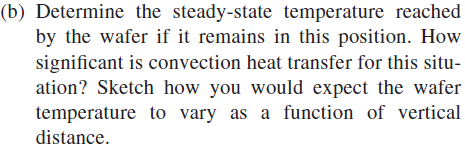

Vi når stedy state når temperaturen stigningen er 0

syms T_wi
q_con_h = h_up * (T_wi - T_amb); %convection above plate
q_con_l = h_low * (T_wi- T_amb); %convection below plate
q_rad_h = epsilon * sigma * (T_h^4 - T_wi^4); %radiation above plate
q_rad_l = epsilon * sigma * (T_c^4 - T_wi^4); %radiation below plate
q_mark = - q_con_h - q_con_l + q_rad_h + q_rad_l;
dTdt_eq = 0 == q_mark / (rho_SiC * c_p * d);

T_wi_steady = vpa(solve(dTdt_eq, T_wi),5)

$$T\_wi\_steady = \left(\begin{array}{c} 1250.8\\ 25.003-1276.3\,\mathrm{i}\\ 24.996+1276.3\,\mathrm{i}\\ -1300.8 \end{array}\right)$$

Her bruger vi den reele løsning der er positiv 1251 K

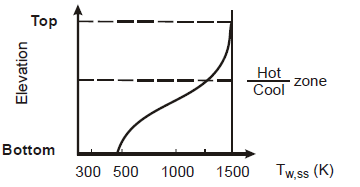


$$W = J/s = \frac{m^2 \cdot kg}{s^{-3}}$$


## Figurer

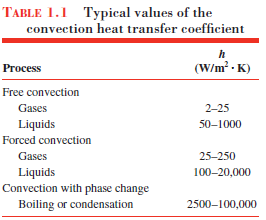

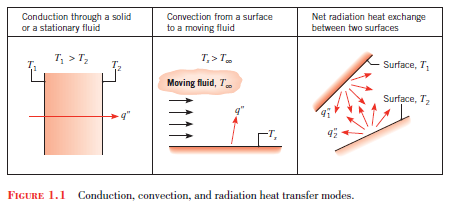

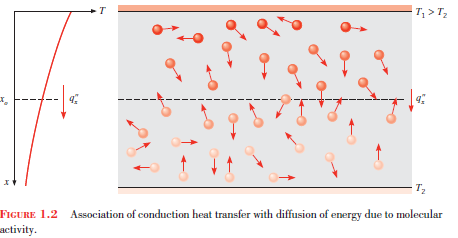

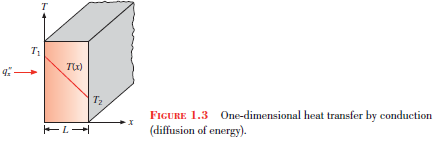

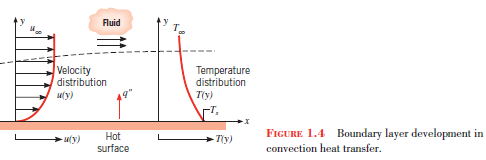

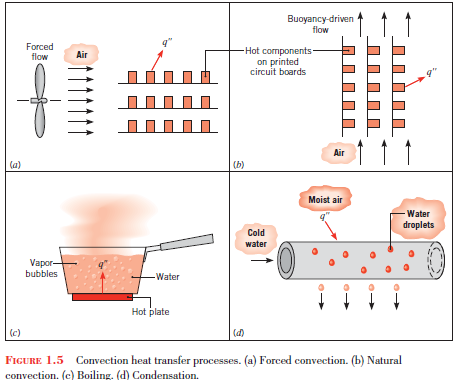

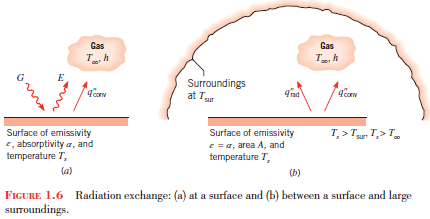

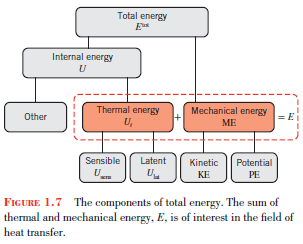

**1. Conservation of Total Energy: First Law of Thermodynamics over a Time Interval (Dt)**

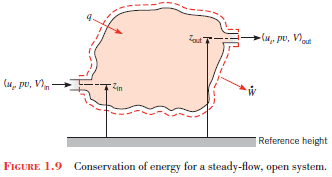

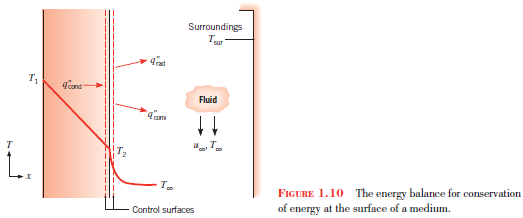

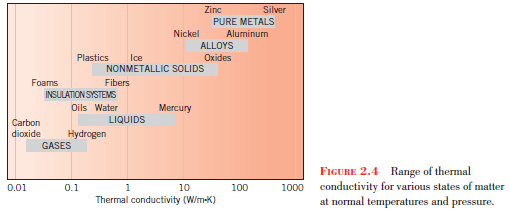

Eksempel 2.3

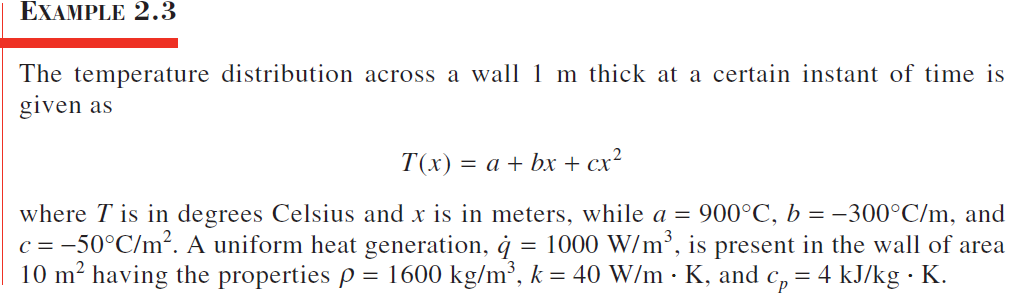

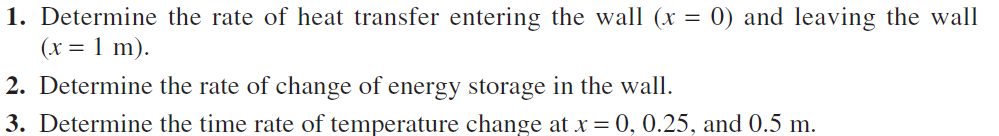

syms x
a = 900;
b = -300;
c = -50;
q_t = 1000; %W/m^3
A = 10; %m^2
rho = 1600; % kg/m^3
k = 40; %W/m * K
c_p = 4; % kJ/kg * K

T = a + b*x + c*x^2 

$$T = -50\,x^{2}-300\,x+900$$


dTdt = diff(T)

$$dTdt = -100\,x-300$$

dTdt_num =matlabFunction(dTdt)

dTdt_num = function_handle with value:
    @(x)x.*-1.0e+2-3.0e+2


% dTdt_num(0)
% dTdt_num(1)

q_in = -k*A*dTdt %fouires formel

$$q\_in = 40000\,x+120000$$


q_left = subs(q_in, x,0)

$$q\_left = 120000$$

q_right = subs(q_in, x,1)

$$q\_right = 160000$$

2 - opstiller energi balance

E_in = q_left;
E_out = q_right;
E_g = q_t * A * 1;

E_st = E_in + E_g - E_out 

$$E\_st = -30000$$